%First some data is simulated which is used to HAVOKc. 
clear
SampleNumber=1000;


%Setting up the A, B and C, matrix
A=[0.6, 0.2; 0.8,-0.1];

B=[1;0]; 

C=[1, 0]; 

%Setting up inital condition:
x=[0;0];


index=2; %Index to save some numbers 
%Making simulation, to obtain data to base modle o
for i=0:SampleNumber-1
    %Determine input
  
    %In general, you can generate N
    %random numbers in the interval (a,b) 
    % with the formula r = a + (b-a).*rand(N,1).
    a=-1;
    b=1;

    u(index-1,1)=a+(b-a)*rand();
      
    x(:,index)=A*x(:,index-1)+B*u(index-1,1);
    y(:,index-1)=C*x(:,index);
    index=index+1;    
end
%**** the way u was make, so it needs to be transposed! 
u=u';

%Getting the HAVOKc model of it
nd=2;  %was 6 the embedded length (the amount for rows=nd*# outputs

r=1; %was 2  How much the SVD is truncated! 

%Getting the model in the V space, and the projection matrix up and down 
%Togehter with all singular values, which can be used to changes truncation
%value
[Av, Bv, Pup, Pdown,S] =HAVOKc_model(y,u,nd,r);


testModel=0; %1=making one step prediction 
%on the data which the model was trained for 
%0=not doing it 

if testModel==1
%Testing the model on the same data it was made on: 
index=1;
    for i=nd:size(y,2)
        uTest=u(i-nd+1:i); 
        yTest=y(i-nd+1:i); 
        
        vT=Pdown*yTest';
        
        uv=Pdown*uTest'; 
        
        xMPC=Av*vT+Bv*uv;
        
        dummy=Pup*xMPC; 
        yPre(index,1)=dummy(end,1);
        index=index+1;
    end

    t=1:size(y(:,nd+1:end),2);
    clf
    yPre=yPre'
    hold on 
    plot(t,y(:,nd+1:end))
    plot(t,yPre(:,1:size(y(:,nd+1:end)+1,2)),'--')
    hold off
end 


%Now there is looked at setting op the setting up the optimziatoin problem 
%First the problem is defined
Problem=optimproblem();

%Afterward the optimizitation variable Delta U is defined. This is achied
%as the number of inputs nu multiplied with the control horizion Hc
nu=size(B,2); % Number of inputs

Hc=10; %Control horizion
Hp=10; %Prediction horizion
 
dU=optimvar('dU',Hc*nu,1);

%Likewise the optimization variable eta is defined. 
% The size of eta corresponds to 2*r, thereby it beocmes: 
ny=size(B,2); %Number of outputs
eta=optimvar('eta',Hp*(r+ny)+(r+ny),1); 
%Next the cost function J, defined in the report, is defined. 
%But First it is neccesary to obtain the lifted weights Q and R 
%All deltaV is multipled with 100, the number of v's=r
Q=[ones(1,r)*100,1];

R=100;

QR=lifting_QR(Q,R,Hp); 

J=0.5*[eta', dU']*QR*[eta; dU]; 

Problem.Objective=J;

%Afterwards there is looked at the constrant constraints, in this case 
%The input slew rate. (input range changes due to the past input changing) 
W=[-1;1]; 
w=[-1;-1]; 

[WLift,wLift] =lifting_slew_rate_constraints(Hc,W,w);

Problem.Constraints.Slew_rate= le(WLift*dU+wLift,zeros(size(WLift,1),1));

Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 1 OptimizationConstraint

  See problem formulation with show.


%Starting to set up the part which will have to changes at each iteration 

ControlRunTime=250; %How long the MPC should run for

%Next there is looked at designing the refarence signal for entire 
%Of the simulation time 
%THe first 100 the refarence is set to 5 afterward it is set to 2. 
%Ref is hard code not good in general! 

Ref=[ones(1,100)*5,ones(1,150)*2];

%Making inital condition for the output measurement, in this case it been 0
DeltaZ0=zeros(nd,1);
DeltaZy=DeltaZ0; 

uMPC=zeros(1,1); 

%States for the "real-world" model  
xMPC=zeros(2,1); 

%Prepring for input range constraints: 

Fis=[-1;1];  %Matrix this uk is mutilpied on
f=[-1;-1];  %constant matrix
[F, f1, f]=lifting_input_constraints(Hc,Fis,f);

%some refarence implemented in the lifting, which is not in used, so just
%defined and "hopefully" never used! 
RefNotUsed=[zeros(1,Hp*r)];  %Some refarence thing present to help a function hopefolly


%Define the inital value of eta_0 for the first time: 
  %Starting by determine the inital value of Eta
    %Determing DeltaV^T: 
    DeltaVtranspose=Pdown*DeltaZy; 

    %Determine Eta0
    eta_0=[DeltaVtranspose;-Ref(1,1)]; 

%Making the for loop part the makes it run
for i=1:ControlRunTime
    %Setting up the input constraints (dependes on the last input) 
    Problem.Constraints.input= F*dU<=-f1*uMPC(:,i)-f; 

  
    %Making lifting for the dynamics 
    [F_eta, Fu, F0, b,F_r] =lifting_dynamics(Av,Bv,Pup,Pdown,nd,r, Hp,Hc,nu,DeltaZ0,eta_0,RefNotUsed,ny);


    %Setting up te dynamics constraints
    Problem.Constraints.dynamics=[F_eta,Fu]*[eta;dU]==(b-F0);

    %That should all the constraints setup now it is possible to solve the
    %optimization problem 
    solution=solve(Problem); 

    %Determine the input value:
    uMPC(:,i+1)=uMPC(:,i)+solution.dU(1,1); 
    
    %Updating the change in 
    DeltaZ0=[solution.dU(1,1);DeltaZ0(1:end-1,1)];



    %Determine DeltaVtransponse, as the prediction, as it would be the same! 
    %Takes out the first DeltaVtranspose, as predited, as it would be the
    %same as prediction down determine it and prediction backup, 
    
    DeltaVtranspose=solution.eta(r+ny+1:2*r+1,:); 



    % Determine the output from the system 
    xMPC(:,i+1)=A*xMPC(:,i)+B*uMPC(:,i+1);
    yMPC(:,i)=C*xMPC(:,i+1);
    eta_0=[DeltaVtranspose;yMPC(:,i)-Ref(:,i)]; 
   
   
end 

Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Solving problem using quadprog.

Minimum found th

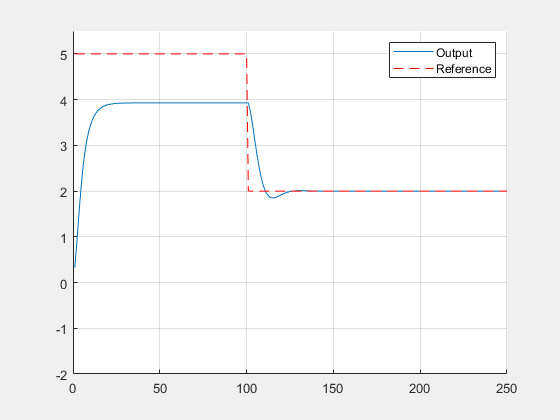

%Justing closing all figures in windows
close all 


%Ploting the system output
figure(1)
figure('Name','System output','NumberTitle','off');
hold on
plot(yMPC)
plot(Ref,'--r')
hold off 
grid
xlim([0 250])
ylim([-2 5.5])
set(gcf,'Visible','on')
legend('Output','Reference')

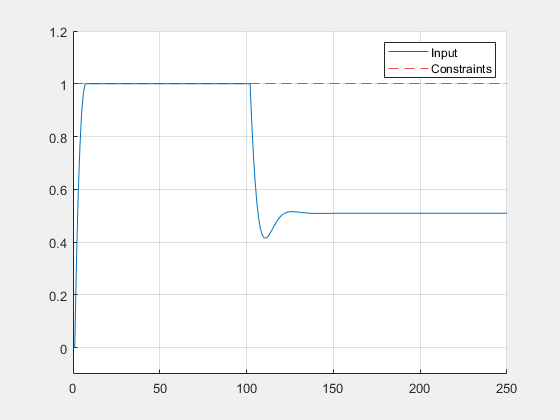



%Plotting the input to the system 
figure(2)
figure('Name','Control input','NumberTitle','off');
hold on 
plot(uMPC)
yline(1,'--r')
hold off 
yline(-1,'--r')
legend('Input','Constraints')
grid 
xlim([0 250])
ylim([-0.1 1.2])
set(gcf,'Visible','on')